# Pull In Data and Store in Variable

%Clear Previous Work
clear all
clc

%Set Directory
cd('ENTER LOCATION HERE')

%Pull in Data
[num,txt,raw] = xlsread('Walk_Test.xlsx');

%Specify Data
measuredTorque = num(5,:);
perscribedTorque = num(6,:);
percentGait = num(13,:);

clear num raw txt

## Find Start and End of Every Gait Cycle

x = 1;  %Initializes internal idx

%Finding starting point
for i = 2:length(percentGait)

    if percentGait(i) == 0 && percentGait(i-1) ~=0
        startIdx(x,1) = i;
        x = x + 1;
    end

end

clear x

%Finding ending point and length
for i = 2:length(startIdx)

    startIdx(i-1,2) = startIdx(i) - 1;
    startIdx(i-1,3) = startIdx(i-1,2) - startIdx(i-1,1);

end

%Removes last, incomplete step
startIdx(end,:) = [];

clear i

## Segment Data into Steps

%Sorts into Steps
for i = 1:length(startIdx)

    mTorque{i} = measuredTorque(1,startIdx(i,1):startIdx(i,2));
    pTorque{i} = perscribedTorque(1,startIdx(i,1):startIdx(i,2));
    pGait{i} = percentGait(1,startIdx(i,1):startIdx(i,2));

end

clear i

%Remove Empty Steps
idxToRemove = [];

for i = 1:numel(mTorque)
    if all(mTorque{i} == 0)
        idxToRemove = [idxToRemove,i];
    end
end

mTorque(idxToRemove) = [];
pTorque(idxToRemove) = [];
pGait(idxToRemove) = [];

model(:,1) = pGait{49}';
model(:,2) = pTorque{49}';


% %Remove Low Setpoint Torques
% for i = 1:numel(pTorque)
%     maxValues(i,1) = max(pTorque{i});
%     maxValues(i,2) = min(pTorque{i});
%     maxValues(i,3) = maxValues(i,1) - maxValues(i,2);
% end
% 
% for i = 2:length(maxValues)  
%     if maxValues(i,1) >= 1 && maxValues(i-1,1) < 1
%         idx(1,1) = i;
%     end
% 
%     if maxValues(i,2) <= -1 && maxValues(i-1,2) > -1
%         idx(1,2) = i;
%     end
% end
% 
% mTorque(1:max(idx)-1) = [];
% pTorque(1:max(idx)-1) = [];
% pGait(1:max(idx)-1) = [];


## Calculate RMSE

for i = 1:length(mTorque)

    for n = 1:length(pTorque{i})
        error(n) = pTorque{i}(n) - mTorque{i}(n);
        squared_errors(n) = error(n)^2;
        mean_squared_errors(i) = mean(squared_errors);
        rmse(i) = sqrt(mean_squared_errors(i));
    end

    clear error squared_errors

end

RMSE = mean(rmse);

## Find the Average Waveform

% Store Data back into one variable
allData = [];
allData2 = [];
allData3 = [];

for i = 1:numel(pGait)
    allData = [allData,pGait{i}];
end

for i = 1:numel(mTorque)
    allData2 = [allData2,mTorque{i}];
end

for i = 1:numel(pTorque)
    allData3 = [allData3,pTorque{i}];
end

data(:,1) = allData;
data(:,2) = allData2;
data(:,3) = allData3;

clear i allData allData2 idx idxToRemove maxValues measuredTorque mTorque percentGait pGait startIdx

%Sort Data based on Percent of Gait Cycle
[~,Idx] = sort(data(:,1));
sortedData = data(Idx,:);

%Find repeating values and average data across those
processedData = [];
pData = [];

unique_values = unique(sortedData(:,1));

for value = unique_values'

    rows_with_value = sortedData(:,1) == value;

    rows_to_average = sortedData(rows_with_value,:);

    averaged_row = mean(rows_to_average,1);
    std_deviation = std(rows_to_average,1);

    processedData = [processedData;averaged_row];
    pData = [pData; std_deviation];

end

%Add in Standard Deviation 
processedData(:,4) = pData(:,2);
processedData(:,5) = pData(:,3);

%Convert Gait Phase to 0-100%
processedData(:,1) = processedData(:,1)*100;

% %Normalize Steps to 0-100%
% for i = 1:length(processedData)
%     pg = resample(processedData(:,1),101,length(processedData(:,1)));
% end

%Store as individual variables
percent_gait = processedData(:,1);
mean_measured_torque = processedData(:,2);
std_measured_torque = processedData(:,4);
mean_perscribed_torque = processedData(:,3);
std_perscribed_torque = processedData(:,5);

clear pData std_deviation Idx averaged_row data idx rows_to_average rows_with_value sortedData unique_values value

## Calculate Timing Parameters

[parameters.Trough_Torque, tPG] = min(processedData(:,2));
parameters.Trough_Percent_Gait = round(processedData(tPG,1));
[parameters.Peak_Torque,pPG] = max(processedData(:,2));
parameters.Peak_Percent_Gait = round(processedData(pPG,1));

parameters.Trough_Torque = round(parameters.Trough_Torque,1);
parameters.Peak_Torque = round(parameters.Peak_Torque,1);

for i = 2:length(processedData(:,1))
    if processedData(i,2) <= 0 && processedData(i-1,2) > 0
        endPoint = processedData(i,1);
    end

    if processedData(i,2) >= 0 && processedData(i-1,2) < 0
        midTime = processedData(i,1);
    end

end

if endPoint < 50
    parameters.Fall_Percent_Gait = (100 - parameters.Peak_Percent_Gait) + endPoint;
    parameters.Rise_Percent_Gait = parameters.Trough_Percent_Gait - endPoint;
else
    parameters.Fall_Percent_Gait = endPoint - parameters.Peak_Percent_Gait;
    parameters.Rise_Percent_Gait = (100 - endPoint) + parameters.Trough_Percent_Gait;
end

parameters.Mid_Percent_Gait = midTime;

parameters.Corrected_Peak_Pecent_Gait = 100-(84 - parameters.Peak_Percent_Gait);
parameters.Corrected_Trough_Percent_Gait = (100-84) + parameters.Trough_Percent_Gait;
parameters.Corrected_Mid_Pecent_Gait = midTime + (100 - 84);


clear pPG tPG endPoint i midTime processedData

## Plot Data and Save Figure

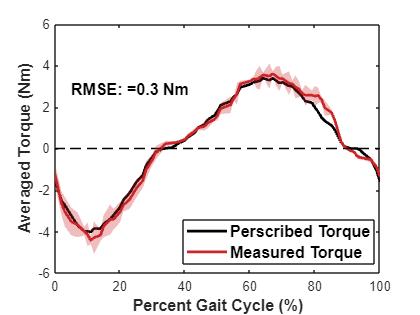

%Standard Gait Cycle
figure;
plot(percent_gait,mean_perscribed_torque,'k','LineWidth',2);
hold on 
plot(percent_gait,mean_measured_torque,'Color',[204 37 41]./255,'LineWidth',2);
hold on
plot(percent_gait,zeros(length(percent_gait)),'k','LineStyle','--');
hold on 
x_fill = [percent_gait;flipud(percent_gait)];
y_fill = [mean_measured_torque + std_measured_torque; flipud(mean_measured_torque-std_measured_torque)];
fill(x_fill,y_fill,[204 37 41]./255,'FaceAlpha',0.3,'EdgeColor','none');
hold on 
text(5,max(mean_perscribed_torque) - 0.5, strcat('RMSE: = ',num2str(round(RMSE,2)),' Nm'),'FontSize',12,'FontWeight','bold');
xlabel('Percent Gait Cycle (%)','FontWeight','bold', 'FontSize',12);
ylabel('Averaged Torque (Nm)','FontWeight','bold','FontSize',12);
legend('Perscribed Torque','Measured Torque','FontWeight','bold','FontSize',12,'Location','best');


%saveas(gcf,'Torque_Profile_Open_Settings_1_2','svg')